# Lab 03: Gripen Aircraft

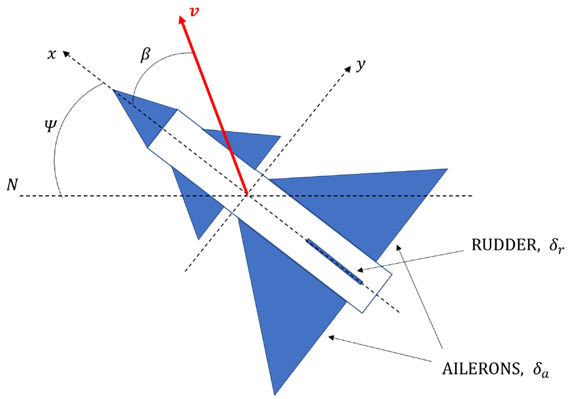       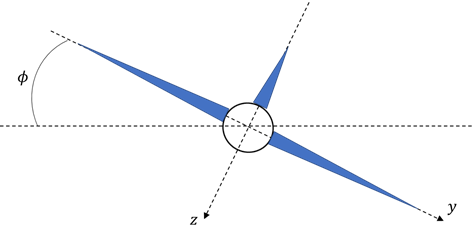

**States**

- $x_1 =v_y \cong \beta \;v$              Velocity [m]                                

- $x_2 =p$                        Roll angular rate [rad/s]             

- $x_3 =r$                         Turning angular rate [rad/s]

- $x_4 =\phi \;$                       Roll angle [rad]

- $x_5 =\Psi \;$                       Course angle [rad]

- $x_6 =\delta_a$                        Aileron angle [rad]

- $x_7 =\delta_r$                        Rudder angle [rad]

**Inputs**

- $u_1 =\delta_a^{\textrm{cmd}}$                    Aileron reference angle [rad]

- $u_2 =\delta_r^{\textrm{cmd}}$                    Rudder reference angle [rad]

**Outputs**

- $y_1 =\phi \;$                        Roll angle [rad]

- $y_2 =\Psi \;$                        Course angle [rad]

**Control Goal:** Track the reference angles $\phi^0 =0$, $\Psi^0 =0$ 

% Load data
load('Gripendata.mat');
%A(1:3, 6:7) = 0;

### 1.a) Analyse the system

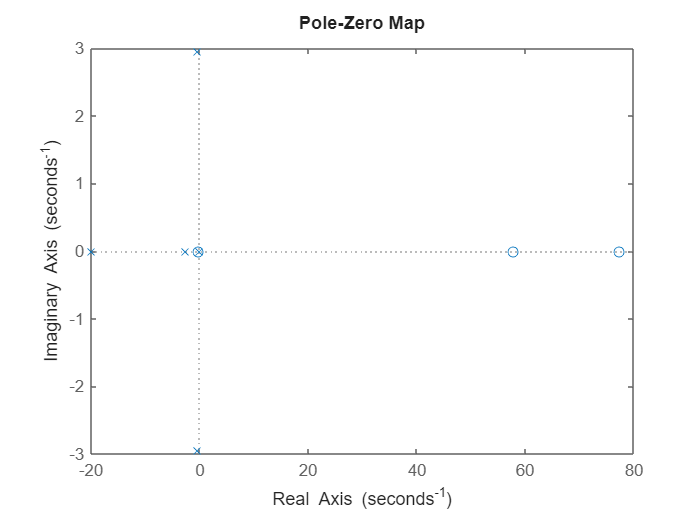

sys_ol = ss(A, B, C, D);
figure(1);
pzmap(sys_ol);

set(findobj(gca, 'type', 'line'), 'MarkerSize', 12);
pole(sys_ol)

ans =    0.0000 + 0.0000i
  -2.5828 + 0.0000i
  -0.3554 + 2.9442i
  -0.3554 - 2.9442i
  -0.0194 + 0.0000i
 -20.0000 + 0.0000i
 -20.0000 + 0.0000i


tzero(sys_ol)

ans =    77.4205
   57.8422
   -0.2107


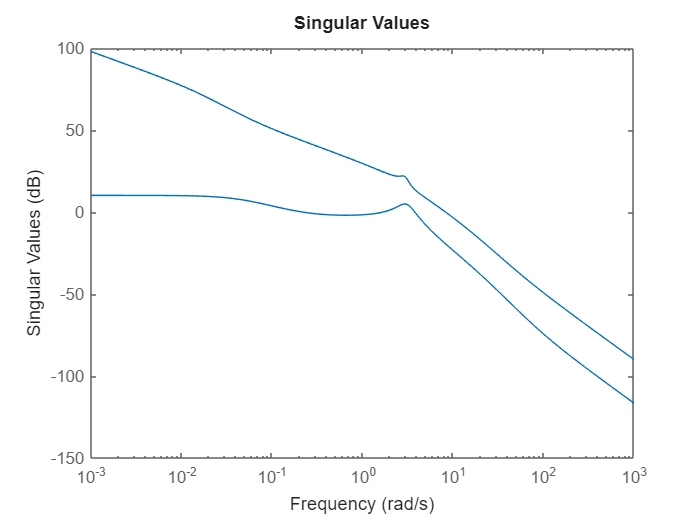

figure(2);
sigma(sys_ol);
set(findobj(gca, 'type', 'line'), 'LineWidth', 2);

### 1.b) Pole placement controller design

Design a pole placement controller assuming that the state is measurable

We first need to check the PP conditions

% Compute the reachability matrix for the pair (A, B)
% M_r = ctrb(A, B); 
% rank(M_r) == n

Then compute the pole placement gain

% pp_desired_poles = [-0.2, -0.3, -0.3, -0.6, -0.6, -20, -20];
% Kpp = place(A, B, pp_desired_poles)

### 1.c) Singular values comparison

Compare the singular values of the system in open loop to those achieved with the pole placement in the loop


$$u=v-K_{\textrm{pp}} x$$



$$\overset{\circ }{x} =A\;x+B\;u=A\;x+B\left(v-K_{\textrm{pp}} x\right)=\left(A-B\;K_{\textrm{pp}} \right)x+B\;\nu \;$$



$$\overset{\circ }{x} =\left(A-B\;K_{\textrm{pp}} \right)x+B\;\nu$$


%sys_cl_pp = ss(A - B * Kpp, B, C, D);
% figure(3);
% sigma(sys_cl_pp);
% set(findobj(gca, 'type', 'line'), 'LineWidth', 2);

### 2.a) State observer design

First check the observability condition

% Compute the observability matrix
% M_o = obsv(A, C);
% rank(M_o) == n

**Define the observer equations and find the observer gain using the Pole Placement Approach**

We adopt a standard observer (*Luenberger Observer*)


$$\overset{\circ}{\hat{x}} = A \hat{x} + B u + L [ y - \hat{y}] = (A - L C) \hat{x} + (B - L D) u + L y$$



$$A^T -C^T L^T \iff A-B\;K$$


And compute the observer gain using `place`

% We can take the observer poles to be sufficiently larger than the PP poles
% obsv_poles = [-10, -20, -20, -30, -30, -100, -100];
% % Remember to transpose properly
% L = place(A', C', obsv_poles)'

### How to implement this observer?


$$\overset{\circ }{\hat{x} } =\underset{A_{\textrm{ob}} }{\underbrace{\left(A-L\;C\right)} } \;\hat{x} +\underset{B_{\textrm{ob}} }{\underbrace{\left\lbrack \begin{array}{cc}
B-LD & L
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
u\\
y
\end{array}\right\rbrack$$



$$y_{\textrm{ob}} =\hat{x}$$


% A_ob = A - L*C;
% B_ob = [ B - L*D, L];
% C_ob = eye(n);
% D_ob = zeros(n, m+p);

### 2.b) Test the closed-loop in simulation

%open('simulation_gripen_regulation.slx')

### 3.a) System enlargement

We first need to verify that there is derivative action!

%tzero(sys_ol)

There are several ways in which we can proceed:

- Augment the system with the integrators' state and design a pole-placement control law for the augmented system (*easier*)

- Compute the transfer function of the PP Controller + Observer, compute the complementary sensitivity transfer function, and design two PI regulators (*design of PIs could be difficult if the sensitivity transfer function is not triangular*)

**First way**: augment the system with integrators


$$\overset{\circ }{\eta \;} =y^0 -y=y^0 -C\;x-D\;u$$


Then


$$\underset{\overset{\;\circ \;}{\tilde{x} } }{\underbrace{\left\lbrack \begin{array}{c}
\overset{\circ }{x} \\
\overset{\circ }{\eta \;} 
\end{array}\right\rbrack } } =\underset{\tilde{A} }{\underbrace{\left\lbrack \begin{array}{cc}
A & \emptyset_{\textrm{nxp}} \\
-C & \emptyset_{\textrm{pxp}} 
\end{array}\right\rbrack } } \tilde{x} +\underset{\tilde{B} }{\underbrace{\left\lbrack \begin{array}{c}
B\\
-D
\end{array}\right\rbrack } } u+\underset{\tilde{M} }{\underbrace{\left\lbrack \begin{array}{c}
\emptyset_{\textrm{nxp}} \\
I_{\textrm{pxp}} 
\end{array}\right\rbrack } } y^0$$


A_tilde = [ A,      zeros(n, p);
            -C,     zeros(p, p)];
B_tilde = [ B;
            -D ];
M_tilde = [ zeros(n, p);
            eye(p) ];

### 3.b) Design of the pole placement for the enlarged system

% en_desired_poles = [ pp_desired_poles, -0.4, -0.4 ];
% Ken = place(A_tilde, B_tilde, en_desired_poles)

Then split the gain as $K_{\textrm{en}} =\left\lbrack \begin{array}{cc}
K_{\textrm{en},x}  & K_{\textrm{en},\eta \;} 
\end{array}\right\rbrack \;$such that $u=-K_{\textrm{en}} \;\tilde{x} =-K_{\textrm{en},x} \;\hat{x} -K_{\textrm{en},\eta \;} \eta \;$

% Ken_x = Ken(:, 1:n);
% Ken_eta = Ken(:, n+1:end);

### 3.c) Test the closed-loop in simulation

%open('simulation_gripen_enlarged.slx');

### **Extra: Analyze the closed-loop singular values**

First of all, we need the closed loop transfer function, having $y^{0\;}$as input and $y$ as output 


$$\left\{ \begin{array}{l}
\overset{\circ}{x}  = A x + B u  \\
\overset{\circ}{\eta} = y^0 - y = y^0 - (C x + Du) = y^0 - \big[Cx + Du \big]  \\
\overset{\circ}{\hat{x}} = A_{ob} \hat{x} + (B-LD) u + Ly = A_{ob} \hat{x} + Bu + L(C x + D u) = A_{ob} \hat{x} + B u+ LC x   \\
y = C x + D u
\end{array}\right.$$


Replacing the control law $u=-K_{\mathrm{en},x} \;\hat{x} -K_{\mathrm{en},\eta \;} \eta \;$we get


$$\left\{ \begin{array}{l}
\overset{\circ}{x} = A  x - B K_{en, \eta} \, \eta - B K_{en,x}  \hat{x} \\
\overset{\circ}{\eta} = y^0 - C  x - D K_{en, \eta} \, \eta - D K_{en,x} \hat{x} \\
\overset{\circ}{\hat{x}} = LC x + - B K_{en, \eta} \,  \eta  + (A_{ob} - B K_{en,x}) \hat{x}   \\
y = C x - D K_{en, \eta} \, \eta - D K_{en, x} \hat{x}
\end{array}\right.$$


Defining $X=\left\lbrack \begin{array}{c}
x\\
\eta \;\\
\hat{x} 
\end{array}\right\rbrack$, we get


$$\overset{\circ }{X} =\left\lbrack \begin{array}{ccc}
A & -BK_{\textrm{en},\eta \;}  & -BK_{\textrm{en},x} \\
-C & -DK_{\textrm{en},\eta \;}  & -DK_{\textrm{en},x} \\
LC & -BK_{\textrm{en},\eta \;}  & A_{\textrm{ob}} -BK_{\textrm{en},x} 
\end{array}\right\rbrack X+\left\lbrack \begin{array}{c}
\emptyset_{\textrm{nxp}} \\
I_{\textrm{pxp}} \\
\emptyset_{\textrm{nxp}} 
\end{array}\right\rbrack y^0$$



$$y=\left\lbrack \begin{array}{ccc}
C & \emptyset_{\textrm{pxp}}  & \emptyset_{\textrm{pxn}} 
\end{array}\right\rbrack X+D\;u$$


% AA = [ A,       -B*Ken_eta,     -B*Ken_x;
%        -C,      -D*Ken_eta,     -D*Ken_x;
%        L*C,     -B*Ken_eta,     A_ob-B*Ken_x];
% BB = [ zeros(n, p);
%        eye(p);
%        zeros(n, p) ];
% CC = [ C, zeros(p, p), zeros(p, n) ];
% DD = D;

Now we can plot the singular values

% figure(4);
% sigma(ss(AA, BB, CC, DD));
% set(findobj(gca, 'type', 'line'), 'LineWidth', 2);


## 4.a) Reduced order observer design

Note that this is possible since $D=0$

First, we need to perform a change of coordinates $T$ such that $x_t =Tx=\left\lbrack \begin{array}{c}
y\\
x_r 
\end{array}\right\rbrack$.

We can take, for example, $x_t =\left\lbrack \begin{array}{ccccccc}
0 & 0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0 & 0\\
1 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack x=\left\lbrack \begin{array}{c}
x_4 \\
x_5 \\
x_1 \\
x_2 \\
x_3 \\
x_6 \\
x_7 
\end{array}\right\rbrack$ where $\left\lbrack \begin{array}{c}
x_4 \\
x_5 
\end{array}\right\rbrack =y$ and $\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_6 \\
x_7 
\end{array}\right\rbrack =x_r$

% T = zeros(n, n);
% T(1, 4) = 1; T(2, 5) = 1;
% T(3, 1) = 1; T(4, 2) = 1;
% T(5, 3) = 1; T(6, 6) = 1;
% T(7, 7) = 1;

Define the matrices of the system in the new coordinates (since $T$ is orthonormal, $T^{-1} =T^T$)

$A_t =TAT^T =\left\lbrack \begin{array}{cc}
A_{\textrm{t11}}  & A_{\textrm{t12}} \\
A_{\textrm{t21}}  & A_{\textrm{t22}} 
\end{array}\right\rbrack$,  $B_t =TB=\left\lbrack \begin{array}{c}
B_{\textrm{t1}} \\
B_{\textrm{t2}} 
\end{array}\right\rbrack$,   $C_t =CT^T =\left\lbrack \begin{array}{cc}
I_{\textrm{pxp}}  & \emptyset_{\textrm{px}\left(n-p\right)} 
\end{array}\right\rbrack$

% At = T*A*T';
% Bt = T*B;
% Ct = C*T';
% 
% At11 = At(1:p, 1:p);
% At12 = At(1:p, p+1:end);
% At21 = At(p+1:end, 1:p);
% At22 = At(p+1:end, p+1:end);
% Bt1 = Bt(1:p, :);
% Bt2 = Bt(p+1:end, :);

The system can hence be re-written as


$$\left\{
\begin{array}{l}
\overset{\circ}{y} = A_{t11} y + A_{t12} x_r
 + B_{t1} u \\
\overset{\circ}{x_r} = A_{t21} y + A_{t22} x_r + B_{t2} u
\end{array}
\right.$$


Then, we move all the known terms in the first equation on the left hand side 


$$\left\{
\begin{array}{l}
\overset{\circ}{y} - A_{t11} y - B_{t1} u = A_{t12} x_r
 \\
\overset{\circ}{{x}_r} =  A_{t22} x_r + B_{t2} u + A_{t21} y
\end{array}
\right.$$


Denoting by 

- $\eta_t =\dot{y} -A_{\textrm{t11}} y-B_{\textrm{t1}} u$ the fictitious output

- $\zeta =B_{\textrm{t2}} u+A_{\textrm{t21}} y$ the fictitious input

we get the reduced-order system


$$\left\{
\begin{array}{l}
\overset{\circ}{{x}_r} =  A_{t22} x_r + \zeta \\
\eta_t = A_{t12} x_r
\end{array} 
\right.$$


**We can now design the observer for the reduced-order system**


$$\overset{\circ \;}{{\hat{x} }_r } =A_{\textrm{t22}} {\hat{x} }_r +\zeta +L_t \left\lbrack \eta_t -A_{\textrm{t12}} {\hat{x} }_r \right\rbrack =\left(A_{\textrm{t22}} -L_t A_{\textrm{t12}} \right){\hat{x} }_r +\zeta +L_t \eta_t$$


%red_desired_poles = [-10, -20, -20, -100, -100];
% Remember to properly transpose
%Lt = place(At22', At12', red_desired_poles)'

**Problem**: $\eta_{t\;} \;$cannot be measured, since it contains $\dot{y}$

**Solution**: substitute the definition of $\eta_t$ and move $\dot{y}$ on the left-hand side


$$\overset{\circ \;}{{\hat{x} }_r } -L_t \overset{\circ }{y} =\left(A_{\textrm{t22}} -L_t A_{\textrm{t12}} \right){\hat{x} }_r +\zeta +L_t \left(-A_{\textrm{t11}} y-B_{\textrm{t1}} u\right)$$


Then define $\xi ={\hat{x} }_r -L_t y$, so we get


$$\overset{\circ }{\xi \;} =\left(A_{\textrm{t22}} -L_t A_{\textrm{t12}} \right)\left(\xi +L_t y\right)+\zeta -L_t A_{\textrm{t11}} y-L_t B_{\textrm{t1}} u=\left(A_{\textrm{t22}} -L_t A_{\textrm{t12}} \right)\xi +\zeta +\left(\left(A_{\textrm{t22}} -L_t A_{\textrm{t12}} \right)L_t -L_t A_{\textrm{t11}} \right)y-L_t B_{\textrm{t1}} u$$


Which, in matricial form, becomes


$$\overset{\circ }{\xi} =\underset{A_{\xi } }{\underbrace{\left(A_{\textrm{t22}} -L_t A_{\textrm{t12}} \right)} } \;\xi +\underset{B_{\xi } }{\underbrace{\left\lbrack \begin{array}{cc}
B_{\textrm{t2}} -L_t B_{\textrm{t1}}  & A_{\textrm{t21}} +\left(A_{\textrm{t22}} -L_t A_{\textrm{t12}} \right)L_t -L_t A_{\textrm{t11}} 
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
u\\
y
\end{array}\right\rbrack$$


%A_xi = At22 - Lt*At12;
%B_xi = [ Bt2 - Lt*Bt1,     At21 + (At22-Lt*At12)*Lt - Lt*At11 ];

*Remark**: When we implement the observer, it estimates the state *$\xi$. The observed state $x_r$ is found as ${\hat{x} }_r =\xi +L_t y$

*Then, *${\hat{x} }_t =\left\lbrack \begin{array}{c}
y\\
{\hat{x} }_r 
\end{array}\right\rbrack \ldotp$* Eventually, a change of coordinates needs to be performed:* $\hat{x} =T^T \;{\hat{x} }_t$

### 4.b) Test the closed-loop performances    

%open('simulation_gripen_roo.slx')

## 5.a) LQ Control  design

Design an LQ controller ensuring closed-loop poles faster than $0\ldotp 05$ rad/s

Then, we design the control law for the pair $\left(\tilde{A} +0\ldotp 05\;I,\tilde{B} \right)$. Taking for example $R=I_{\textrm{mxm}}$ and $Q=I_{\left(n+p\right)\times \left(n+p\right)}$, we must check the following conditions:

    1. $\left(\tilde{A} +0\ldotp 05I,\tilde{B} \right)$is reachable

rank(ctrb(A_tilde + 0.05*eye(n+p), B_tilde)) == n+p

ans = logical
   1


    2. $\left(\tilde{A} +0\ldotp 05\;I,C_q \right)$ is observable, where $C_q$ is such that $C_q^T \;C_q =Q$

Q = eye(n+p);
R = eye(m);
rank(obsv(A_tilde + 0.05*eye(n+p), sqrt(Q))) == n+p

ans = logical
   1


Klq = lqr(A_tilde + 0.05*eye(n+p), B_tilde, Q, R)

Klq =    -0.1618    0.7343    4.4112   -0.3348   51.6196    3.7513   -0.5704    1.3778   -2.5748
    0.4539    0.9177  -13.6902    4.8044  -85.4217    1.2290    3.3800   -4.6037   -0.5530


Klq_x = Klq(:, 1:n);
Klq_eta = Klq(:, n+1:end);

### 6) Kalman Filter design

Conditions:

    1. $\left(A,C\right)$ is observable

rank(obsv(A, C)) == n

ans = logical
   1


    2. $\left(A,{\tilde{B} }_q \right)$ is reachable

Q_tilde = eye(n);
R_tilde = eye(p);
rank(ctrb(A, sqrt(Q_tilde))) == n

ans = logical
   1


Lkf = lqr(A.', C.', Q_tilde, R_tilde).'

Lkf =    -4.2813  -12.8050
    2.2406    0.4220
   -0.2170    0.0633
    2.3367    0.0611
    0.0611    1.0596
    0.0053    0.0002
    0.0003   -0.0005


A_kf = A - Lkf*C;
B_kf = [ B - Lkf*D, Lkf];
C_kf = eye(n);
D_kf = zeros(n, m+p);